# Explore **PASSIVE** rotations which Transform a G vec into a B vec

In this tutorial, we're going to explore the concept of **PASSIVE** rotation matrices. 

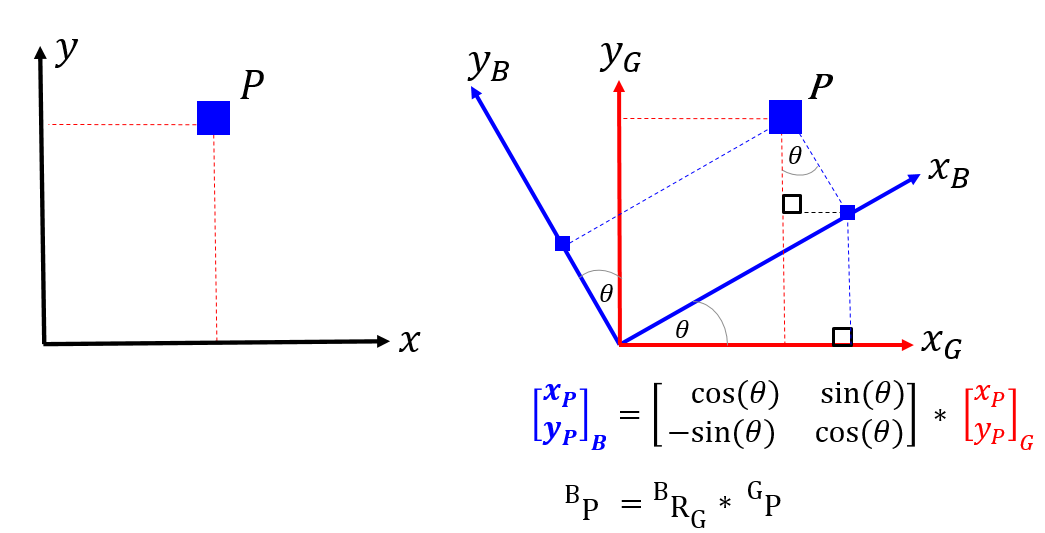

**Why are we doing this ?**

- Rotation matrices are used heavily in Mechanical, Robotic and Aeronautical engineering applications.

- Often students can get confused when they read the term "Rotation matrix".  In many/most cases, this confusion can be reduced by emphasizing a rotation matrix as being either PASSIVE or ACTIVE.

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Introduction:

Consider the following scenario: 

- We have a data point $P$.

- We have a fixed frame called the **G-fame.**

- We know the *(x,y) *co-ordinates of the point $P$ in this **G-fame** and refer to this as ${^GP}$.

- We then rotate the **B-frame** relative to the fixed **G-frame**. 

We now want to know what the co-ordinate of the point $P$ is relative to this new **B-frame, **ie: what is ${^BP}$ ?  This scenario is shown in the figure below:

 

A **PASSIVE** rotation matrix ${^BR_G}$, converts the co-ordinates of a point expressed in a fixed **G-frame**, into the co-ordinates of the same point expressed in the new **B-frame**. 

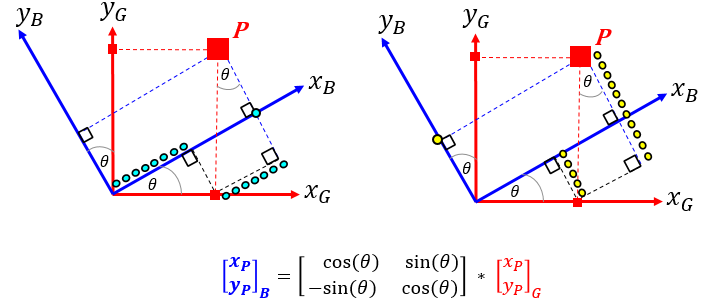

## A concrete example - part 1:

Consider the specific case of ${^GP} = \pmatrix{ 3 \cr 1 \cr 0} $ and a B-frame rotated by 60 degrees relative to Z axis of the  G-frame

gP    = [3,1,0]';
alpha = 60*pi/180;

bRg   = [   cos(alpha), sin(alpha),  0;
           -sin(alpha), cos(alpha),  0;
                     0,          0,  1];
 

So now apply the passive rotation matrix and calculate $^BP$

      
bP = bRg * gP   

bP =     2.3660
   -2.0981
         0


## A concrete example - part 2:

We can implement the formula for this passive rotation matrix ${^BR_G}$ into a MATLAB class called <`bh_rot_passive_G2B_CLS`>.  This will allow us to reuse the formula over and over again. So repeating the previous example we have:

gP     = [3, 1, 0]';

OBJ_PR = bh_rot_passive_G2B_CLS({'D1Z'}, alpha, 'RADIANS');

R      = OBJ_PR.get_R1();
bP     = R * gP 

bP =     2.3660
   -2.0981
         0


## An example of 3 successive PASSIVE rotations

In the previous example we considered just 1 rotation.  Consider now the scenario of performing a sequence of rotations. As before, say we have a fixed G-frame. We start by having our B-frame co-incident with G, and then we start to rotate the B-frame. Specifically, we're going to apply 3 LOCAL axes rotations which will result in a newly orientated B-frame.  Assume that we apply these 3 successive rotations in the following order:

- R1Z occurs 1st about the LOCAL **Z** body axis $(\phi)$, aka **YAW**

- R2Y occurs 2nd about the LOCAL **Y** body axis $(\theta)$, aka **PITCH**

- R3X occurs 3rd about the LOCAL **X** body axis $(\psi)$, aka **ROLL**

We can express a vector defined in the G axis to it's corresponding description in the B axis, using a sequence of **PASSIVE** rotation matrices, ie:


$$\bf ^Bv = R3X(\psi_x) \enspace \times \enspace 
R2Y(\theta_y) \enspace \times \enspace R1Z(\phi_z) \enspace \times \enspace {^Gv}$$


    OR, in a more compact form as:


$$\bf ^Bv = {^BR_G} \enspace \times \enspace {^Gv}$$


## Let's explore:

Let's explore these 3 passive rotations using the MATLAB class <`bh_rot_passive_G2B_CLS`> that we used earlier.  Note in the code below how we are stating that the 1st rotation $\phi $ is about the local Z axis (ie: D1Z), and the second rotation $\theta $ is then around the local Y axis (ie: D2Y), and the 3rd rotation $\psi$ is then around the local X axis (ie: D3X).  In the example below we're alos going to use "symbolic" variables for our rotation angles.

OBJ_B = bh_rot_passive_G2B_CLS({'D1Z', 'D2Y', 'D3X'}, [sym('phi'), sym('theta'), sym('psi')], 'SYM')

OBJ_B =   bh_rot_passive_G2B_CLS with properties:

        ang_units: SYM
    num_rotations: 3
          dir_1st: D1Z
          dir_2nd: D2Y
          dir_3rd: D3X
          ang_1st: [1x1 sym]
          ang_2nd: [1x1 sym]
          ang_3rd: [1x1 sym]


The symbolic PASSIVE rotation matrices

R1 = OBJ_B.get_R1

$$R1 = \left(\begin{array}{ccc} \cos\left(\phi \right) & \sin\left(\phi \right) & 0\\ -\sin\left(\phi \right) & \cos\left(\phi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R2 = OBJ_B.get_R2

$$R2 = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & -\sin\left(\theta \right)\\ 0 & 1 & 0\\ \sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

R3 = OBJ_B.get_R3

$$R3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\psi \right) & \sin\left(\psi \right)\\ 0 & -\sin\left(\psi \right) & \cos\left(\psi \right) \end{array}\right)$$

## Here are some compound PASSIVE rotation matrices - part 1

R2R1       = OBJ_B.get_R2R1

$$R2R1 = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & -\sin\left(\theta \right)\\ -\sin\left(\phi \right) & \cos\left(\phi \right) & 0\\ \cos\left(\phi \right)\,\sin\left(\theta \right) & \sin\left(\phi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

Note that "R2R1" is the same thing as "R2*R1":

diff_mat   = R2R1 - R2*R1   % this should be zero

$$diff\_mat = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Here are some compound PASSIVE rotation matrices - part 2

R3R2R1     = OBJ_B.get_R3R2R1

$$R3R2R1 = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & -\sin\left(\theta \right)\\ \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

Note that "`R3R2R1`" is the same thing as "`R3*R2*R1`":

diff_mat_B = R3R2R1 - R3*R2*R1    % this should be zero

$$diff\_mat\_B = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Here's the PASSIVE rotation matrix ${^BR_G}$

bRg = R3*R2*R1

$$bRg = \left(\begin{array}{ccc} \cos\left(\phi \right)\,\cos\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\phi \right) & -\sin\left(\theta \right)\\ \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right) & \cos\left(\phi \right)\,\cos\left(\psi \right)+\sin\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\psi \right)\\ \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\psi \right)\,\sin\left(\phi \right)\,\sin\left(\theta \right)-\cos\left(\phi \right)\,\sin\left(\psi \right) & \cos\left(\psi \right)\,\cos\left(\theta \right) \end{array}\right)$$

## Transform a vector in G, into its components in B

vG    = [1,0,0]';
bRg   = OBJ_B.get_R3R2R1;
vB    = bRg*vG

$$vB = \left(\begin{array}{c} \cos\left(\phi \right)\,\cos\left(\theta \right)\\ \cos\left(\phi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)-\cos\left(\psi \right)\,\sin\left(\phi \right)\\ \sin\left(\phi \right)\,\sin\left(\psi \right)+\cos\left(\phi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right) \end{array}\right)$$

## Transform a vector in G, into its components in B - alternate syntax

vG              = [1,0,0]';
vB_2nd_approach = OBJ_B.apply_R3R2R1(vG);

Note what the "`apply_R3R2R1(vG)`" method does the same thing as "`R3R2R1 * vG`"

diff_vB         = vB - vB_2nd_approach    % this should be zero

$$diff\_vB = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

# Next steps:

If you found this tutorial interesting, there are 2 others that you may want to look at:

- **bhLIVE_TUT_rot_passive_G2B_example_3_euler_rates_CONCEPT.mlx** : In this tutorial we see an application of PASSIVE rotation matrices that comes from the modelling of aerial vehicles.

- **bhLIVE_TUT_rot_ACTIVE_B2G_example_1_CONCEPT.mlx **: In this tutorial we introduce the concept of the ACTIVE rotation matrix.